%trapezoid reimann sum approximation
y = NaN(91,1);
for i = 10:100
    y(i-9) = trapinteg(i,0,3);
end
n = 10:100

n =     10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59


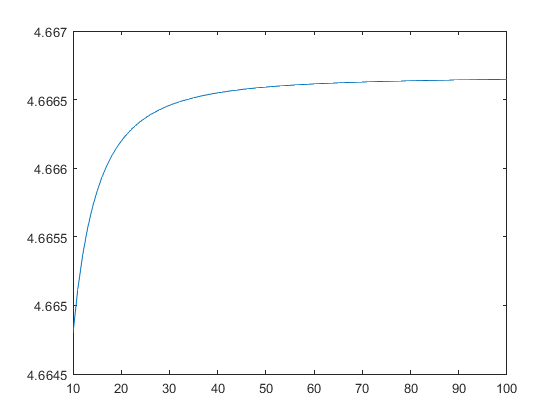

plot(n,y)

function [y,t] = trapinteg(n,lowbound,upbound)
    dx = (upbound-lowbound)/n;
    t = lowbound:dx:upbound;
    timesteps = lowbound+dx:dx:upbound;
    f = @(x)sqrt(x+1);
    
    y = sum((f(timesteps) + f(timesteps-dx))/2*dx);
    
end